## Metody numeryczne – Laboratorium 2

### Zadanie 1. Page Rank

Agnieszka Delmaczyńska, 184592

Informatyka 2021/2022, semestr 4, grupa 1

**Zadanie.** Celem laboratorium jest implementacja algorytmu PageRank, który jest podstawą sukcesu firmy Google. Pozwala on na badanie jakości stron w sieci na podstawie relacji między poszczególnymi stronami.

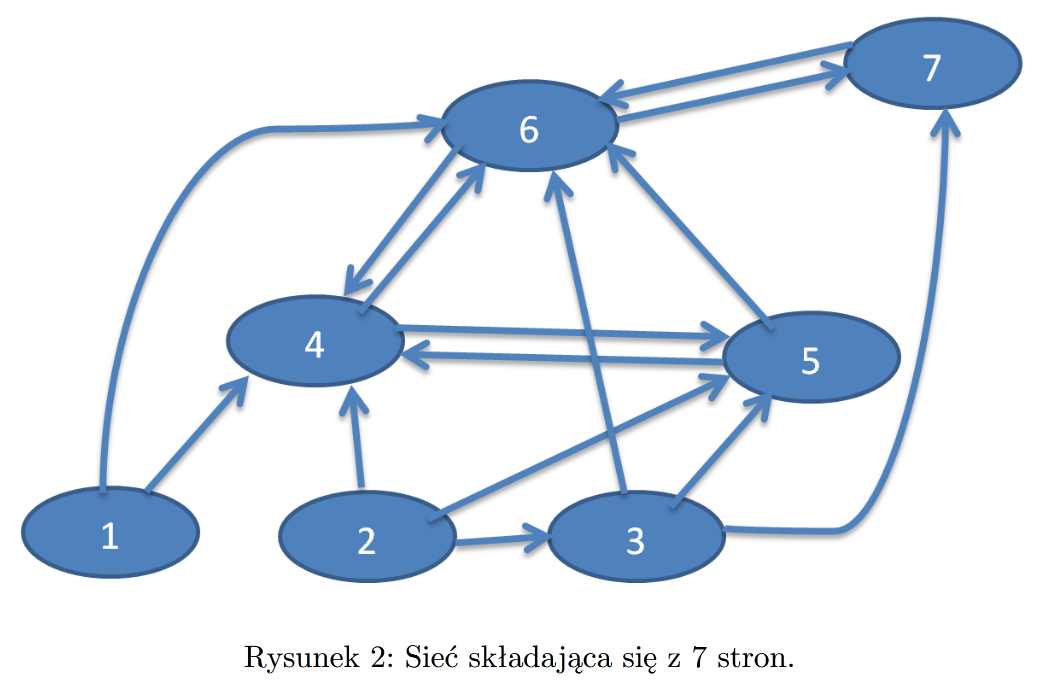

Na początek czyszczę Okno poleceń i pole Workspace.

clc   % clear Command Window
clear % clear Workspace

Generuję tablicę Edges dla sieci z rys. 2, zawierającej 7 stron.

% zadanie A
Edges = sparse([1,1,2,2,2,3,3,3,4,4,5,5,6,6,7;
    4,6,3,4,5,5,6,7,5,6,4,6,4,7,6]);

Konstruuję macierze A, B, I i wektor b dla połączeń wygenerowanych w Zadaniu A dla parametru d = 0.85. Wszystkie macierze są przechowywane w formacie sparse, ponieważ są to macierze rzadkie. Odpowiednie elementy macierzy B są niezerowe.

% zadanie B
N = max(max(Edges));             % N = 7, liczba stron
liczba_polaczen = size(Edges,2); % liczba_polaczen = 15
d = 0.85;                        % d - współczynnik tłumienia
I = speye(N);                    % I - macierz jednostkowa 7x7
disp(I);

   (1,1)        1
   (2,2)        1
   (3,3)        1
   (4,4)        1
   (5,5)        1
   (6,6)        1
   (7,7)        1



b = ones(N,1)*(1-d)/N;           % wektor b o długości N
disp(b);

    0.0214
    0.0214
    0.0214
    0.0214
    0.0214
    0.0214
    0.0214



% B = sparse(N,N);                 % generuje macierz 0 m x n
% for i = 1: liczba_polaczen
%     B(Edges(2, i), Edges(1, i)) = 1; % wpisz 1 tam, gdzie jest połączenie
% end
B = sparse( Edges(2, : ) , Edges(1, :) , 1, N, N);
disp(B);

   (4,1)        1
   (6,1)        1
   (3,2)        1
   (4,2)        1
   (5,2)        1
   (5,3)        1
   (6,3)        1
   (7,3)        1
   (5,4)        1
   (6,4)        1
   (4,5)        1
   (6,5)        1
   (4,6)        1
   (7,6)        1
   (6,7)        1




L = sum(B);                      % wpisz ile łącznie jest połączeń
                                 % dla danej strony, w wektorze
A = sparse(diag(1./L));          % macierz rzadka, na przekątnej elementy = 1/L(i)
disp(A);

   (1,1)       0.5000
   (2,2)       0.3333
   (3,3)       0.3333
   (4,4)       0.5000
   (5,5)       0.5000
   (6,6)       0.5000
   (7,7)       1.0000



M = sparse(I - d*(B*A));         % macierz rzadka
disp(M);

   (1,1)       1.0000
   (4,1)      -0.4250
   (6,1)      -0.4250
   (2,2)       1.0000
   (3,2)      -0.2833
   (4,2)      -0.2833
   (5,2)      -0.2833
   (3,3)       1.0000
   (5,3)      -0.2833
   (6,3)      -0.2833
   (7,3)      -0.2833
   (4,4)       1.0000
   (5,4)      -0.4250
   (6,4)      -0.4250
   (4,5)      -0.4250
   (5,5)       1.0000
   (6,5)      -0.4250
   (4,6)      -0.4250
   (6,6)       1.0000
   (7,6)      -0.4250
   (6,7)      -0.8500
   (7,7)       1.0000



 Rozwiązuję układ równań  za pomocą metody bezpośredniej (r = M\b).

% zadanie C
% M * r = b
r = M\b;
disp(r);

    0.0214
    0.0214
    0.0275
    0.2488
    0.1410
    0.3583
    0.1815



Tworzę wykres bar(r), na którym można zaobserwować wartość PageRank dla poszczególnych stron w sieci.

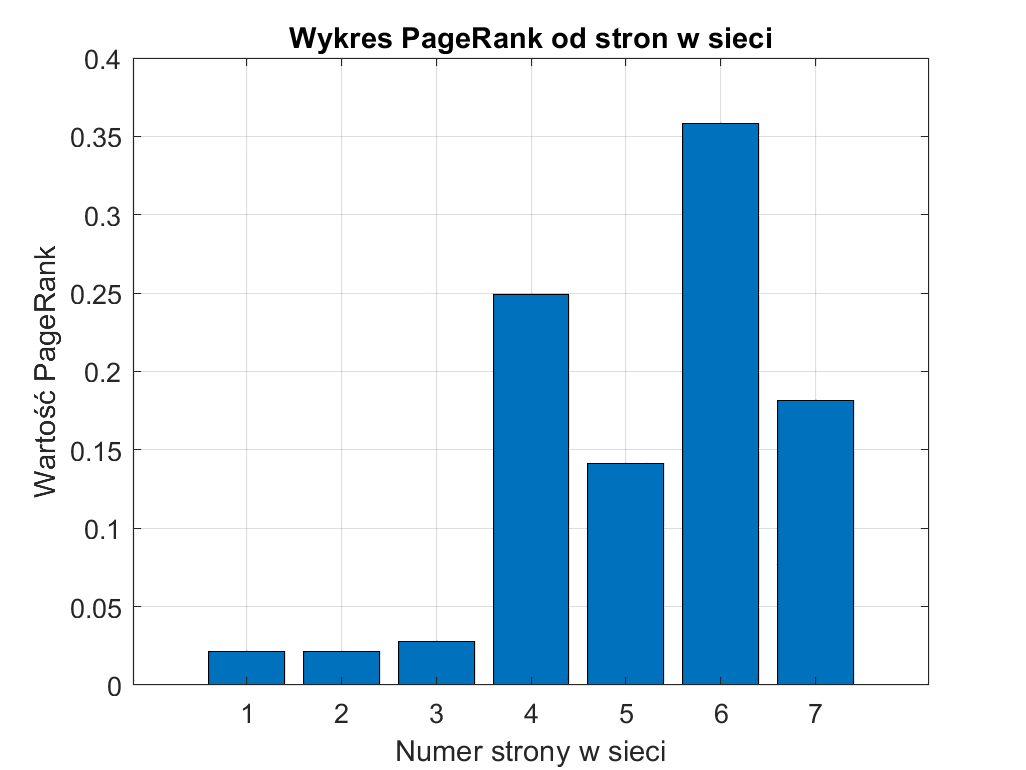

% zadanie D
bar(r)
title('Wykres PageRank od stron w sieci');
xlabel('Numer strony w sieci');
ylabel('Wartość PageRank');
grid on;
saveas(gcf,'PageRank_wykres.png');